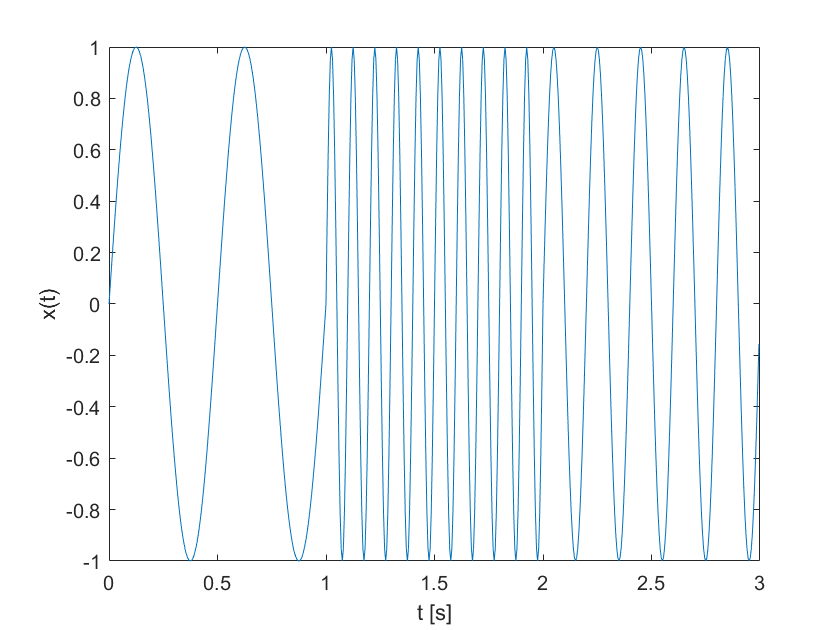

fs=200; dt=1/fs;
t=0:dt:1-dt;
x1=sin(2*pi*2*t); x2=sin(2*pi*10*t); x3=sin(2*pi*5*t);
x=[x1,x2,x3]; tt=[t,t+1,t+2];
figure(1), plot(tt,x), xlabel('t [s]'), ylabel('x(t)');

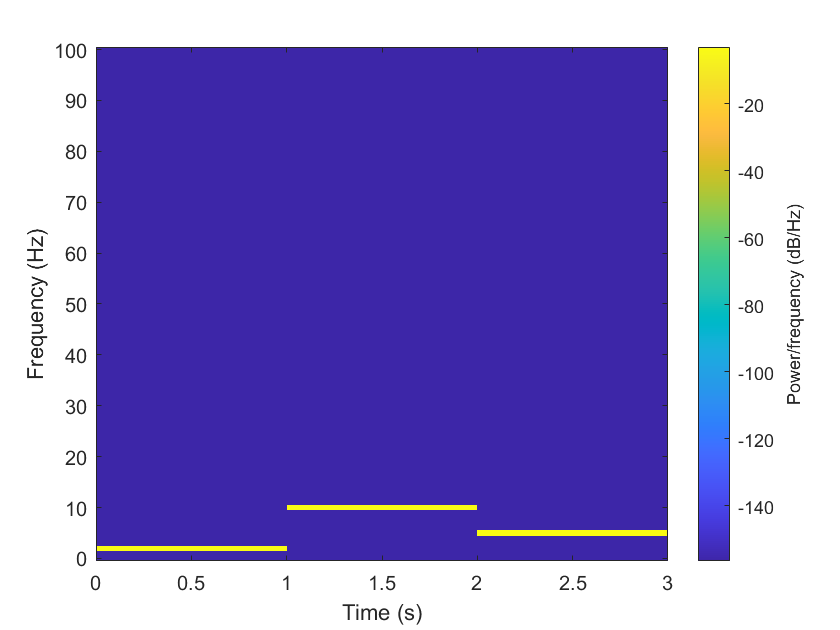

figure(2), spectrogram(x,rectwin(200),0,200, fs,'yaxis');

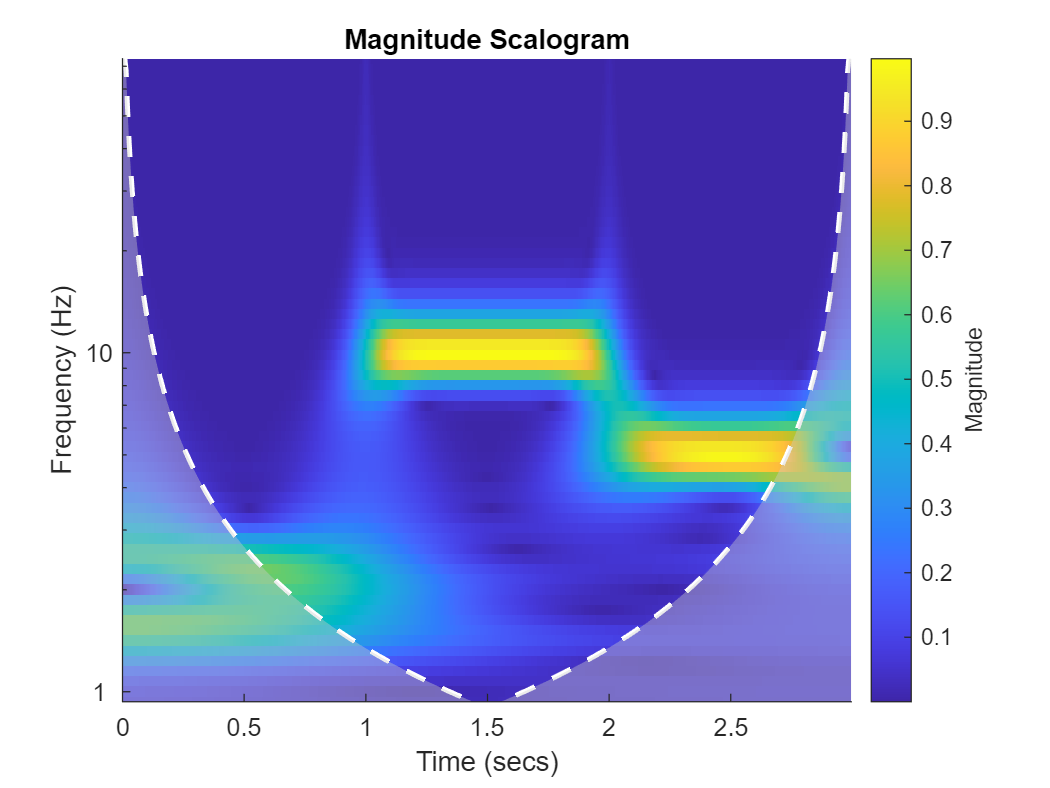

cwt(x,'amor',fs)

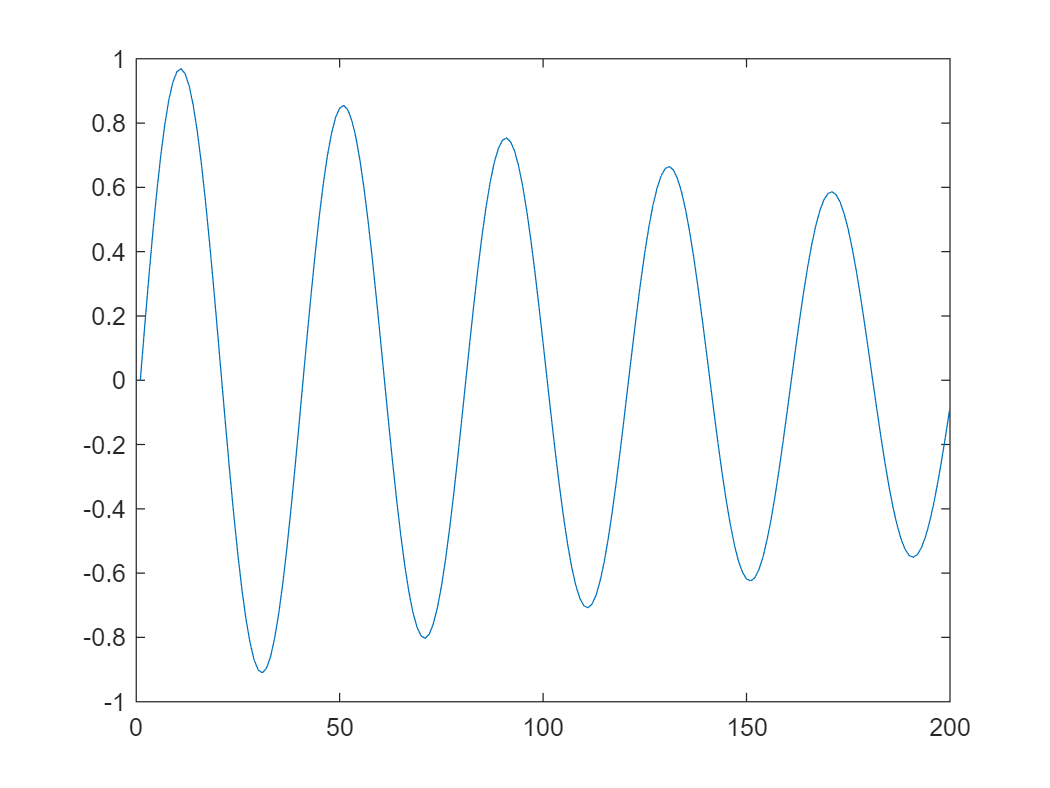


e=exp(-0.02*2*pi*5*t).*sin(2*pi*5*t);
plot(e)

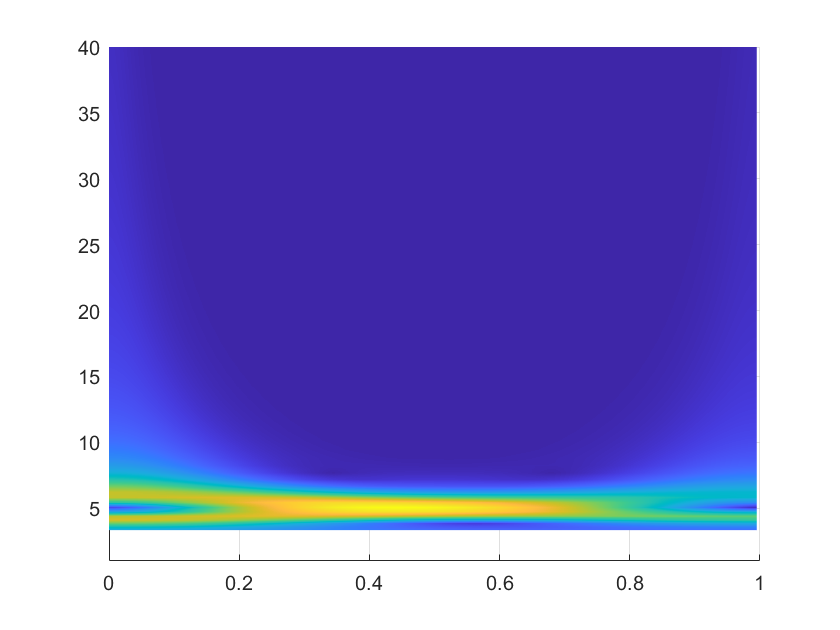

[c,f]=cwt(e,fs);
ff = repmat(f',length(t),1);
tt = repmat(t,length(f),1);
figure, surf(tt,ff',abs(c)), shading interp;
ylim([1 40]), view([0 90])